clc,clear,close all;
% load gifty toolbox to read gii format (surface-based data)
% import surface data of Freesurfer tempalte 

% Vertices: location of individual points (x,y,z) or nodes that make up a surface mesh 

% Faces:  the polygons formed by connecting the vertices of a surface mesh model
% the faces are defined by indices that specify which vertices are connected to form each face. 
% These indices are usually stored in groups of three, representing the three vertices that form a triangular face
init;

g_mesh = struct with fields:
       faces: [655360×3 int32]
         mat: [4×4 double]
    vertices: [327684×3 single]


g_lh = struct with fields:
       faces: [327680×3 int32]
         mat: [4×4 double]
    vertices: [163842×3 single]


g_rh = struct with fields:
       faces: [327680×3 int32]
         mat: [4×4 double]
    vertices: [163842×3 single]


% total vertices are 327684, each hemisphere brain has 163842 
% (we can use a template with small number of vertices)
n_vertices = size(g_mesh.vertices,1)

n_vertices = 327684

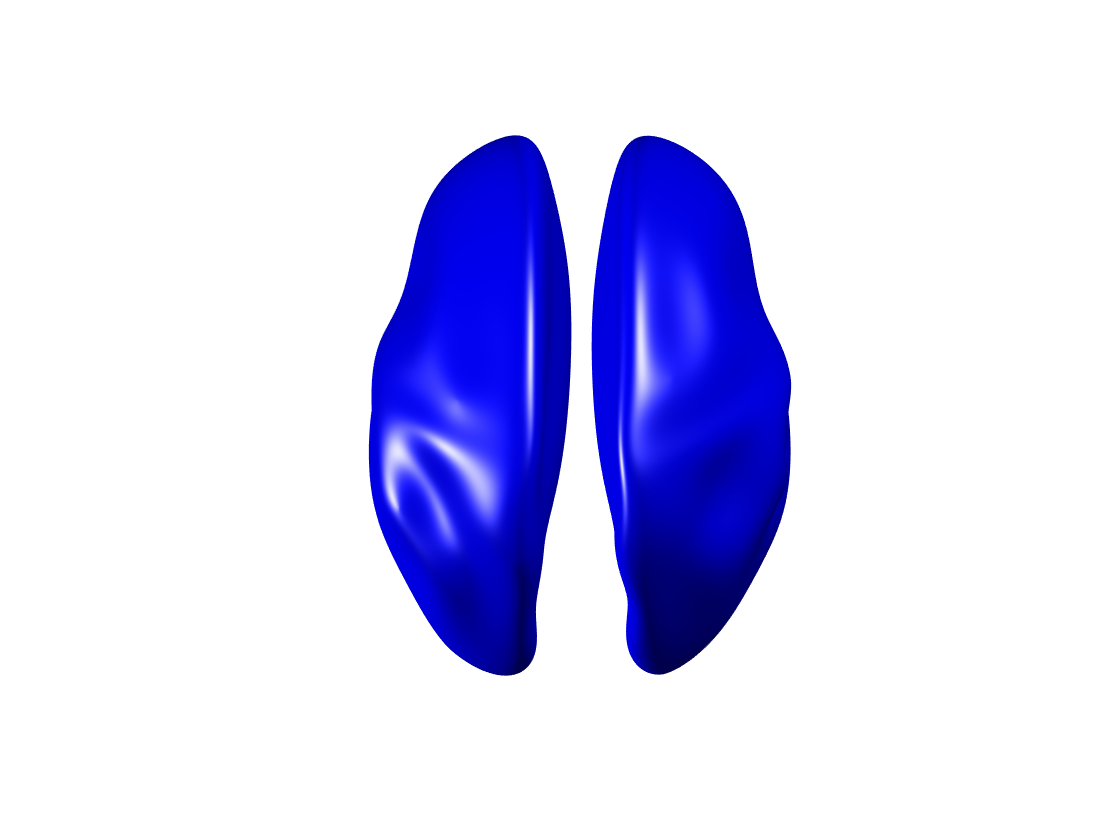

figure;
%plot brain surface without weight 
plot(g_mesh)

%plot brain surface with weight from atlas
%note that Schaefer atlas is not symmetric, we have to read anotation of
%both left and right hemisphere brain.
% read annotation: 101 regions in left brain (100 region + medial wall brain) 
[~,gg_lh1_cdata,lh_mapping_table] = read_annotation('brainspace/lh.Schaefer2018_200Parcels_7Networks_order.annot');
lh_mapping_table

lh_mapping_table = struct with fields:
      numEntries: 101
        orig_tab: 'Schaefer2018_200Parcels_7Networks'
    struct_names: {101×1 cell}
           table: [101×5 double]


% read annotation: 101 regions in right brain (100 region + medial wall brain) 
[~,gg_rh1_cdata,rh_mapping_table] = read_annotation('brainspace/rh.Schaefer2018_200Parcels_7Networks_order.annot');
rh_mapping_table

rh_mapping_table = struct with fields:
      numEntries: 101
        orig_tab: 'Schaefer2018_200Parcels_7Networks'
    struct_names: {101×1 cell}
           table: [101×5 double]


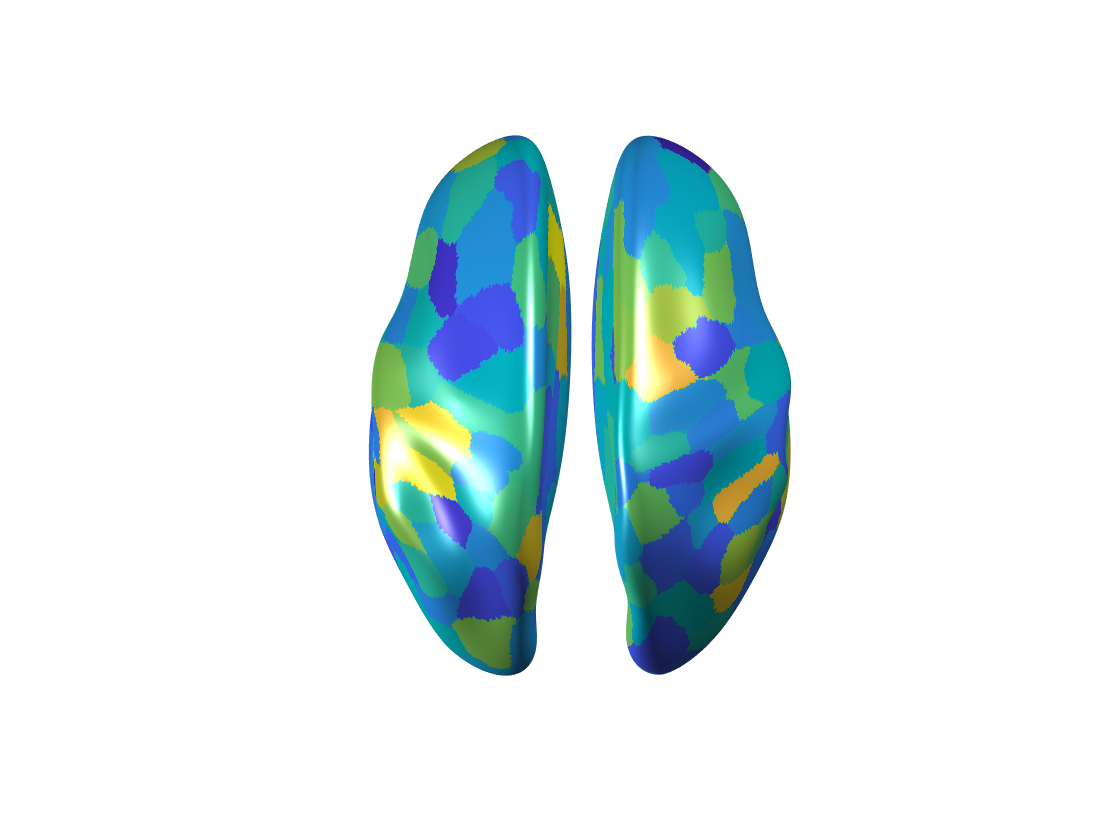

%each regions has specific ID

lh_atlas_id = lh_mapping_table.table(:,5);
rh_atlas_id = rh_mapping_table.table(:,5);

table = readtable('data/mean.layer.0.csv');
corticalThicknesses = double(table2array(table(:,2)));
% convert weight of 200 regions to weight in brain surface
w_left_cdata  = zeros(n_vertices/2,1);
w_right_cdata = zeros(n_vertices/2,1);
for j=1:size(corticalThicknesses,1)/2
  % vlookup mapping table
  w_left_cdata(find(gg_lh1_cdata == lh_atlas_id(j))) = corticalThicknesses(2*j-1);
  w_right_cdata(find(gg_rh1_cdata == rh_atlas_id(j))) = corticalThicknesses(2*j);
end
final_cdata = [w_left_cdata;w_right_cdata];
gg_mesh.cdata = final_cdata;
figure;
plot(g_mesh,gg_mesh)

matlab.internal.liveeditor.openAndConvert ('tutorial.mlx', 'tutorial.pdf', 'HideCode', true);